clear all 
clc

robot = loadrobot('kukaIiwa14');
robot.DataFormat = 'column';

dt = 0.002;
num_snaps = 5000;
num_traj = 10;
t_span = 0:dt:dt*num_snaps;
num_states = length(homeConfiguration(robot));

num_wp = 20;
for i = 1:num_traj
    i
    lim_upper = deg2rad([60, 40, 60, 60, 90, 90, 100]');
    lim_lower = -lim_upper;



    %%%generate path
    t_end = dt*num_snaps; 
    for s = 1:num_wp
        if s == 1
            q_wp(:,s) = randomConfiguration(robot)';
            q_wp(:,s) = sat_lim(q_wp(:,s),lim_upper, lim_lower);
            t_wp(:,1) = 0;
            q_wp_dot = 0.2*(2*rand(num_states,1) - 1);
        else
            t_wp(s) = s*t_end/num_wp;
%             q_wp(:,s) = randomConfiguration(kuka)';
            q_wp(:,s) = q_wp(:,s-1) + q_wp_dot*(t_wp(s)-t_wp(s-1));
            q_wp(:,s) = sat_lim(q_wp(:,s),lim_upper, lim_lower);
            q_wp_dot = 0.4*(2*rand(num_states,1) - 1);
        end

        % %%%X(i,s,1:num_states) = reshape(q_wp(:,s),[1,1,7]);

    end

    [q_traj, qd_traj, qddot_traj] = minjerkpolytraj(q_wp,t_wp,length(t_span));

    X((3*i-3)*num_states+1:(3*i-2)*num_states,:) = q_traj;
    X((3*i-2)*num_states+1:(3*i-1)*num_states,:) = qd_traj;%.*ul_joints; %joint velocity
    X((3*i-1)*num_states+1:(3*i)*num_states,:) = qddot_traj;
end 

i = 1

i = 2

i = 3

i = 4

i = 5

i = 6

i = 7

i = 8

i = 9

i = 10

plot_lim = repmat(lim_upper,1,length(t_span))

plot_lim =     1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472    1.0472
    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.6981    0.69

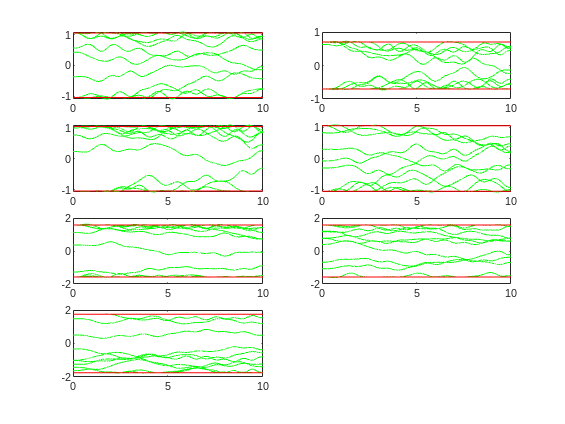

figure()
for i = 1:num_states
    subplot(4,2,i)
    xlabel('t')
    ylabel(strcat('th',num2str(i)))
    for j = 1:num_traj
        plot(t_span,X((3*j-3)*num_states+i,:),'g', t_span,plot_lim(i,:) ,'r',t_span,-plot_lim(i,:) ,'r')
        hold on

    end
end

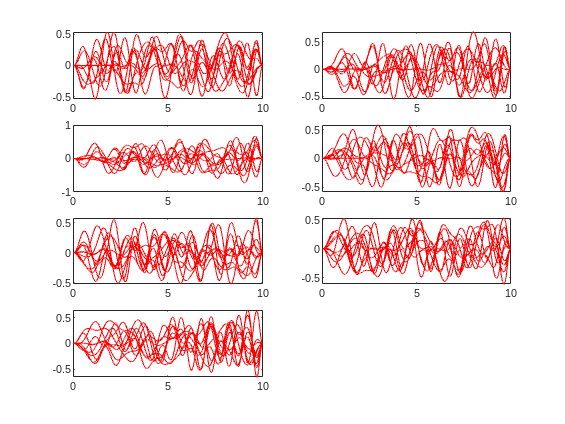

figure()
for i = 1:num_states
    subplot(4,2,i)
    xlabel('t')
    ylabel(strcat('th dot ',num2str(i)))
    for j = 1:num_traj
         plot(t_span,X((3*j-2)*num_states+i,:),'r')
        hold on

    end
end

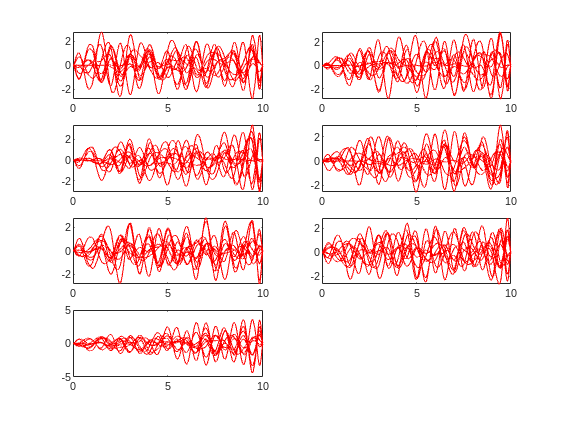

figure()
for i = 1:num_states
    subplot(4,2,i)
    xlabel('t')
    ylabel(strcat('th ddot ',num2str(i)))
    for j = 1:num_traj
         plot(t_span,X((3*j-1)*num_states+i,:),'r')
        hold on

    end
end

writematrix(X, 'data.csv')
